# BMM: Data exploration

In this script, we will explore the raw data and plot simple figure to get a better grasp of the data

## Download the data

% quantity={'dens','ff','dd','n_all','DBZH','w'};
% addpath('functions/'); 

Download all data

% d = download_vp(start_date);
% save('./data/d_all.mat','d','quantity','start_date','end_date')

 Download only the data we need

start_date=datetime(2018,02,01,12,00,00);
end_date=datetime(2018,09,31,12,00,00);
d = download_vp(start_date,end_date,quantity);
save('./data/d2018.mat','d','quantity','start_date','end_date','-v7.3')

Pre-treatment for all data

load('./data/d_all.mat')
figure; hold on;
for i_d=1:numel(d)
    plot(d(i_d).time,i_d,'.k')
end
datetick('x'); yticklabels({d.name}); yticks(1:numel(d));

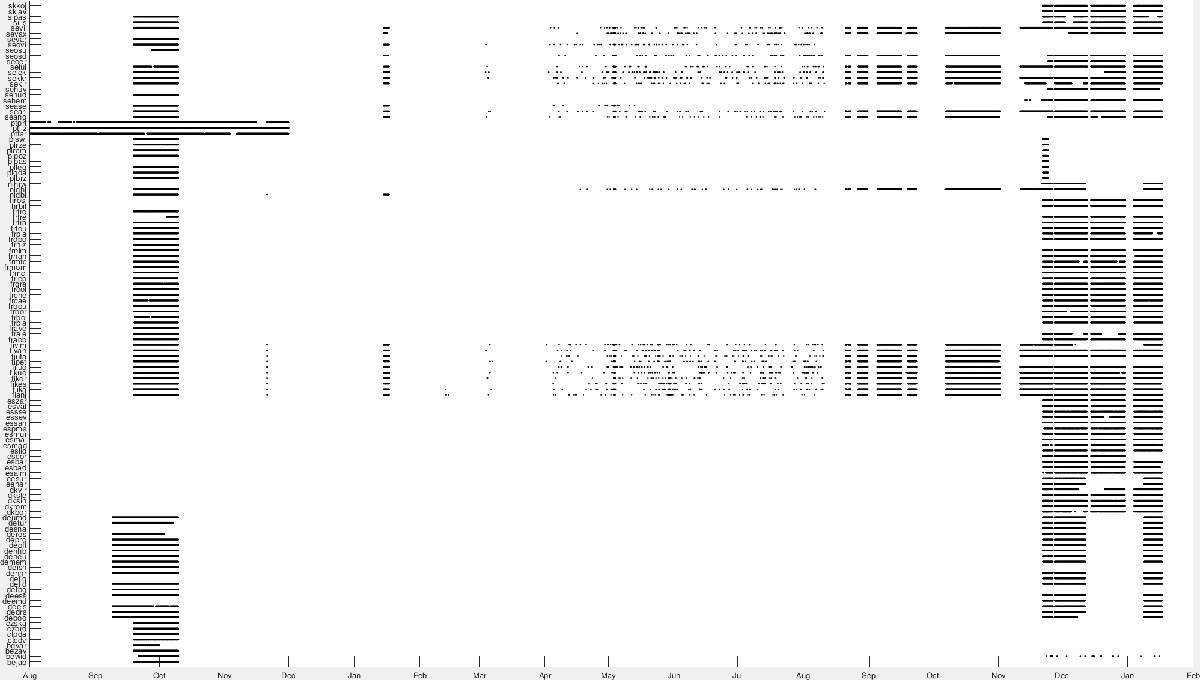

## Exploring Figure

Loading the data

load('./data/d2018.mat')

Plot location of all radars with their coverage as the size of the circle

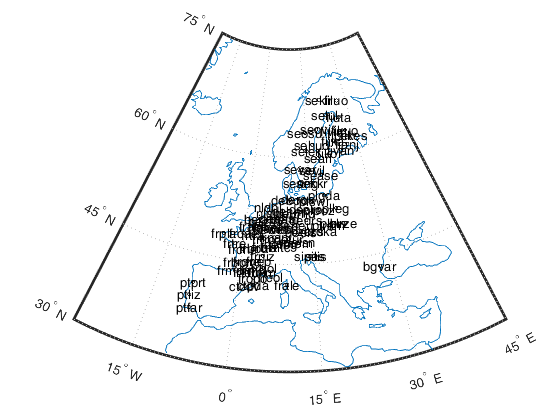

figure; hold on;
worldmap('Europe');
load coastlines; plotm(coastlat, coastlon)
circlem([d.lat],[d.lon],[d.maxrange])

textm([d.lat],[d.lon],{d.name},'HorizontalAlignment','center')

Plot timeseries of all quantity for all radars

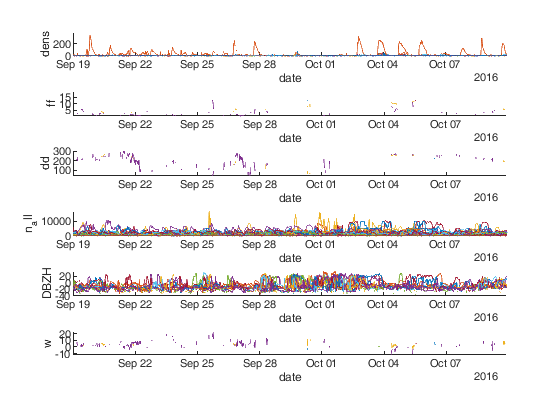

figure; 
for i_quantity=1:numel(quantity)
    subplot(numel(quantity),1,i_quantity); hold on;
    for i_d=1:numel(d)
        plot(d(i_d).time, nanmean(d(i_d).(quantity{i_quantity}),2))
    end
    axis tight; xlabel('date'); ylabel(quantity{i_quantity});
end

Plot the ratio of NaN (Not-a-Number) through all time, for each radar and by altitude

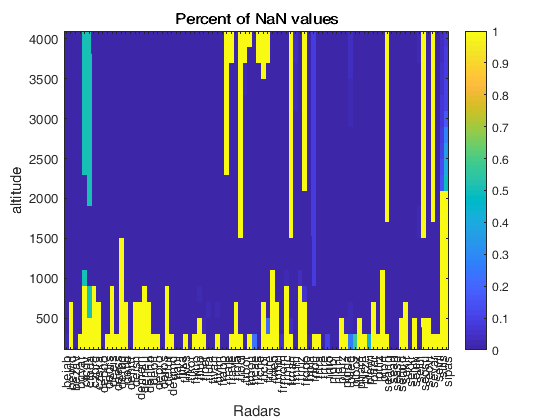

h=nan(numel(d),20);
for i_d=1:numel(d)
    h(i_d,:) = mean(isnan(d(i_d).dens(:,1:20)));
end
figure; imagesc(1:numel(d),(1:20)*200,h');
xlabel('Radars');ylabel('altitude')
set(gca, 'YDir', 'normal');xticklabels({d.name});xticks(1:numel(d)); xtickangle(90);colorbar;
title('Percent of NaN values')

Plot the ratio of NaN on the map

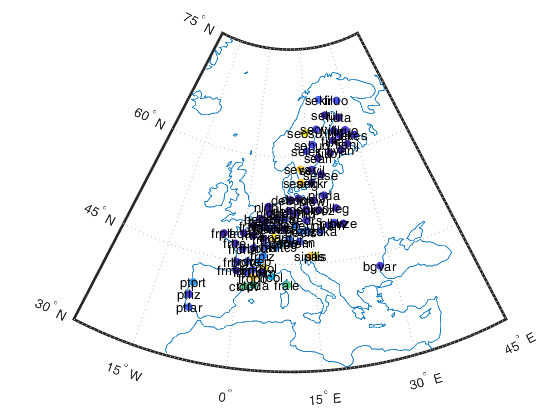

h3=nan(numel(d),1);
for i_d=1:numel(d)
    tmp = d(i_d).dens(:,1:20);
    h3(i_d)=mean(isnan(tmp(:)));
end
figure; hold on;
worldmap('Europe');
load coastlines; plotm(coastlat, coastlon)
scatterm([d.lat],[d.lon],[],h3,'filled')
textm([d.lat],[d.lon],{d.name},'HorizontalAlignment','center')

Plot the ratio of NaN by date (hour)

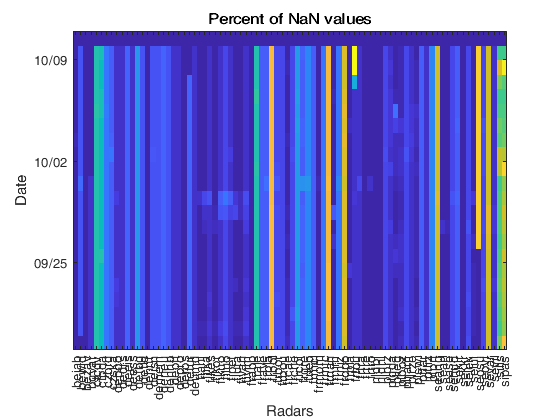

datehour=start_date:end_date;
h2=nan(numel(d),numel(datehour));
for i_date = 1:numel(datehour)
    for i_d=1:numel(d)
        id = d(i_d).time>datehour(i_date) & d(i_d).time<datehour(i_date)+1;
        h2(i_d,i_date)=mean(mean(isnan(d(i_d).dens(id,:)))); % including
        % the gap in altimetric
        % h2(i_d,i_date)=mean(isnan(nanmean(d(i_d).dens(id,:),2))); % once the altimetric gap are filled.
    end
end
figure; imagesc(1:numel(d),datenum(datehour),h2'); 
xlabel('Radars');ylabel('Date')
set(gca, 'YDir', 'normal');
xticks(1:numel(d)); xticklabels({d.name}); xtickangle(90); datetick('y'); axis tight
title('Percent of NaN values')

Plot a specific station by name

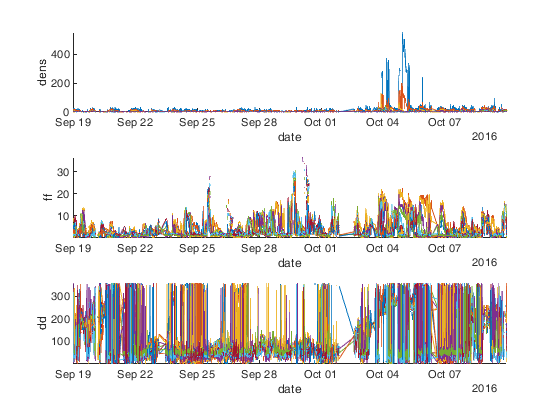

figure; hold on;
i_d=strcmp({d.name},'frnim');
i_d=1;
for i_quantity=1:3
    subplot(3,1,i_quantity); hold on;
    plot(d(i_d).time, d(i_d).(quantity{i_quantity}))
    axis tight; xlabel('date'); ylabel(quantity{i_quantity});
end

Plot and export for each radar the bird density (log scale) with raw reflectivity

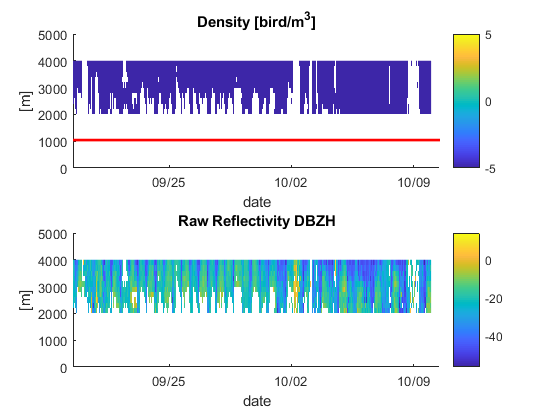

for i_d=1:numel(d)

    if d(i_d).interval>0
        figure(1); clf; set(gcf, 'Color', 'w');
        subplot(2,1,1); hold on;
        imagesc(datenum(d(i_d).time), d(i_d).interval*(1/2:double(d(i_d).levels)), log10(d(i_d).dens)','AlphaData',~isnan(d(i_d).dens'))
        plot([datenum(start_date) datenum(end_date)],[d(i_d).height d(i_d).height],'r','linewidth',2); caxis([-2.3 2.3])
        ylabel('[m]'); title('Density [log10 bird/m^3]');datetick('x','dd/mm','keeplimits');   colorbar;
        datetick('x'); axis([datenum(start_date) datenum(end_date) 0 5000]); set(gca, 'YDir', 'normal')
        
        subplot(2,1,2); hold on;
        imagesc(datenum(d(i_d).time), d(i_d).interval*(1/2:double(d(i_d).levels)), d(i_d).DBZH','AlphaData',~isnan(d(i_d).DBZH'))
        xlabel('date'); ylabel('[m]'); title('Raw Reflectivity DBZH');colorbar;
        axis([datenum(start_date) datenum(end_date) 0 5000]); datetick('x','mm','keeplimits'); set(gca, 'YDir', 'normal')
        % axis([datenum(start_date+59) datenum(end_date-154) 0 5000]); datetick('x','dd/mm','keeplimits'); set(gca, 'YDir', 'normal')
        export_fig(['figure2018/April_' num2str(i_d) '_' d(i_d).name '.png'],'-png')
    end
end

Plot and export for each radar the bird flight speed and direction 

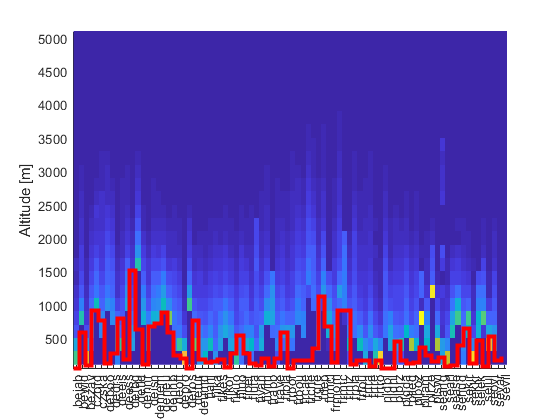

for i_d=1:numel(d)
    figure(1); clf; set(gcf, 'Color', 'w');
    subplot(2,1,1); hold on;
    imagesc(datenum(d(i_d).time), d(i_d).interval*(1/2:double(d(i_d).levels)), d(i_d).ff','AlphaData',~isnan(d(i_d).ff'))
    plot([datenum(start_date) datenum(end_date)],[d(i_d).height d(i_d).height],'r','linewidth',2); caxis([0 40])
    xlabel('date'); ylabel('[m]'); title('Bird flight ground speed [m/s]'); colorbar;
    datetick('x'); axis([datenum(start_date) datenum(end_date) 0 5000]); set(gca, 'YDir', 'normal')
    
    subplot(2,1,2); hold on;

    imagesc(datenum(d(i_d).time), d(i_d).interval*(1/2:double(d(i_d).levels)), d(i_d).dd','AlphaData',~isnan(d(i_d).dd'))
    xlabel('date'); ylabel('[m]'); title('Bird flight direction');colorbar;
    datetick('x'); axis([datenum(start_date) datenum(end_date) 0 5000]); set(gca, 'YDir', 'normal')
    export_fig(['figure/V_' num2str(i_d) '_' d(i_d).name '.png'],'-png')
end

Altitude

A=nan(numel(d),25);

Undefined function or variable 'dhour'.

for i_d=1:numel(d)
   a = nanmean(d(i_d).dens);
   A(i_d,:) = [a nan(1,25-numel(a))];
end
figure(23);clf; hold on;
imagesc(1:numel(dc),(1:25)*200,(A./nansum(A,2))'); stairs(0.5:1:numel(dc)-0.5,[dc.height],'r','linewidth',3)
set(gca, 'YDir', 'normal');
xticks(1:numel(dc)); xticklabels({dc.name}); xtickangle(90); ylabel('Altitude [m]'); axis tight

Comparaison with after cleaning

load('./data/d.mat')
d_before=d;
load('./data/dc_corr.mat')
d_after=dc;

for i_d=1:numel(d)
    if d(i_d).interval>0

Undefined function or variable 'dhour'.

        figure(6); clf; set(gcf, 'Color', 'w');

        subplot(2,1,1); hold on;
        imagesc(datenum(d_before(i_d).time), d_before(i_d).interval*(1/2:double(d_before(i_d).levels)), log10(d_before(i_d).dens)','AlphaData',~isnan(d_before(i_d).dens'))
        xlabel('date'); ylabel('[m]'); title('Density After Cleaning [log10 bird/m^3]');colorbar; caxis([-2.3 2.3])
        axis([datenum(start_date) datenum(end_date) 0 5000]); datetick('x','dd/mm','keeplimits'); set(gca, 'YDir', 'normal')
        
        subplot(2,1,2); hold on;
        i_da = find(strcmp({d_after.name},d_before(i_d).name));
        if (i_da>0)
            imagesc(datenum(d_after(i_da).time), d_after(i_da).interval*(1/2:double(d_after(i_da).levels)), log10(d_after(i_da).dens)','AlphaData',~isnan(d_after(i_da).dens'))
            plot([datenum(start_date) datenum(end_date)],[d_after(i_da).height d_after(i_da).height],'r','linewidth',2); caxis([-2.3 2.3])
            ylabel('[m]'); title('Density Before Cleaning [log10 bird/m^3]');datetick('x','dd/mm','keeplimits');   colorbar;
            datetick('x'); axis([datenum(start_date) datenum(end_date) 0 5000]); set(gca, 'YDir', 'normal');
        end
        export_fig(['figure\corrected\' num2str(i_d) '_' d_before(i_d).name '.png'],'-png')
    end
end

## Centre de gravity

Find and plot the center of gravity of the migration 

cghour(:,1) = nansum(bsxfun(@times,dhour,[d.lat]'))./nansum(dhour);
cghour(:,2) = nansum(bsxfun(@times,dhour,[d.lon]'))./nansum(dhour);

cgday(:,1) = nansum(bsxfun(@times,dday,[d.lat]'))./nansum(dday);
cgday(:,2) = nansum(bsxfun(@times,dday,[d.lon]'))./nansum(dday);

figure; hold on;
imagesc(datenum(datehour),[0 15],daynight,'AlphaData',daynight/2)
quiver(datenum(datehour(1:end-1)+diff(datehour)/2)',zeros(size(cghour,1)-1,1),diff(cghour(:,1)),diff(cghour(:,2)))
datetick('x'); axis([datenum(datehour(1)) datenum(datehour(end)) -1 1]);

figure;
quiver(datenum(hour(datehour(1:end-1)+diff(datehour)/2))',zeros(size(cghour,1)-1,1),diff(cghour(:,1)),diff(cghour(:,2)))

## Distribution fitting

d2=round(dhour*pi*25^2);

Log-normal Transform

d2log=d2(:);
d2log(d2log==0 | isnan(d2log))=[]; % Removing two 0 values... 
logpd = fitdist((d2log),'lognormal');

 Exponential

exppd = fitdist(d2(:),'exp');

Gamma

gampd = fitdist(d2(:),'gamma');

Plot

x=min(d2(:)):max(d2(:));
figure; hold on;
histogram(d2(:),'Normalization','pdf'); 
plot(x,lognpdf(x,logpd.mu,logpd.sigma),'linewidth',2)
plot(x,exppdf(x, exppd.mu),'linewidth',2)
plot(x,gampdf(x, gampd.a,gampd.b),'linewidth',2)
plot(x,poisspdf(x, poipd.lambda),'linewidth',2)
legend({'EPDF','Log','Exp','Gamma','Poisson'})

## Plot dynamic map

load coastlines; 
h=figure(2);
F(numel(datehour)) = struct('cdata',[],'colormap',[]); 
daynight=hour(datehour)>18|hour(datehour)<6;
logpd = fitdist(dhour(dhour~=0 & ~isnan(dhour)),'lognormal');
d3=(log(dhour)-logpd.mu)/logpd.sigma;
for i_date = 1:numel(datehour)
    clf;
    subplot(3,1,[1 2]); hold on;
    worldmap('Europe');
    plotm(coastlat, coastlon)
    scatterm(lat,lon,maxrange*4,d3(:,i_date),'filled');
    id = isnan(d3(:,i_date));
    scatterm(lat(id),lon(id),maxrange(id)*4,[.5 .5 .5],'filled');
    plotm(cghour(i_date,1),cghour(i_date,2),'or','MarkerFaceColor','r')
    if i_date>1&&i_date<numel(datehour)
        deltalat= (cghour(i_date+1,1)-cghour(i_date-1,1))/2;
        deltalon= (cghour(i_date+1,2)-cghour(i_date-1,2))/2;
        quiverm(cghour(i_date,1),cghour(i_date,2),deltalat,deltalon,'r')
    end
    caxis([-2 2])
    title(datestr(datehour(i_date)))
    subplot(3,1,3); hold on;
    imagesc(datenum(datehour),[0 max(nanmean(dhour))],daynight,'AlphaData',daynight/2); caxis([0 1000])
    plot(datenum(datehour), nanmean(dhour), 'linewidth',2); ylabel('Average of dens'); 
    plot([datenum(datehour(i_date)) datenum(datehour(i_date))],[0 max(nanmean(dhour))],'r','linewidth',2);
    datetick('x'); axis([datenum(datehour(1)) datenum(datehour(end)) 0 max(nanmean(dhour))]);
    drawnow;
    F(i_date) = getframe(h);
end

Export in a file

figure; movie(F,4,2)
v=VideoWriter('Hour.avi');
v.FrameRate = 12;  % Default 30
v.Quality = 75;
open(v);
writeVideo(v, F);
close(v);


## Interpolation

x=-9:0.5:30;
Y=35:0.5:68;
z=datenum(start_date):datenum(end_date);
[xq,yq,zq] = meshgrid(x,Y,z);

d2=dday;
ddate=dateday;
logpd = fitdist(d2(d2~=0 & ~isnan(d2)),'lognormal');
d3=(log(d2)-logpd.mu)/logpd.sigma;

% 3D
lat=[d.lat];
lon=[d.lon];
maxrange = [d.maxrange];
[DDATE, LAT] = meshgrid(ddate,lat);
[~, LON] = meshgrid(ddate,lon);

F=scatteredInterpolant(LON(~isnan(d3)),LAT(~isnan(d3)),datenum(DDATE(~isnan(d3))),d3(~isnan(d3)),'natural','none');
vq = F(xq,yq,zq);


% 2.5D
[xq,yq] = meshgrid(x,Y);
vq=nan(numel(Y),numel(x),numel(ddate));
for i_date=1:numel(ddate)
    id=~isnan(d3(:,i_date));
    if sum(id)>0
        F=scatteredInterpolant(lon(id)',lat(id)',d3(id,i_date),'linear');
        vq(:,:,i_date) = F(xq,yq);
    end
end


% figure
h=figure(2);
load coastlines; 
F2(numel(ddate)) = struct('cdata',[],'colormap',[]); 
for i_date = 1:numel(ddate)
    clf;
    worldmap('Europe');
   
    R = georasterref('RasterSize', size(vq),'Latlim', [min(Y) max(Y)], 'Lonlim', [min(x) max(x)]);
    meshm(vq(:,:,i_date), R)
    
    plotm(coastlat, coastlon,'k')
    id = isnan(d3(:,i_date));
    scatterm(lat(~id),lon(~id),maxrange(~id)*4,d3(~id,i_date),'filled','MarkerEdgeColor','k');
    scatterm(lat(id),lon(id),maxrange(id)*4,[.5 .5 .5],'filled','MarkerEdgeColor','k');
    title(datestr(ddate(i_date))); caxis([-2 2])
    drawnow;
    F2(i_date) = getframe(h);
end

v=VideoWriter('DayInterp.avi');
v.FrameRate = 1;  % Default 30
v.Quality = 75;
open(v);
writeVideo(v, F2);
close(v);
